clearvars;

samples = 500

samples = 500

Ustawienia

Filename = "sin.wav";
Bit_resolution = 2;
PDF = "rectangular";
Noise_shaping = false;


Wczytanie pliku i wygenerowanie szumu

[x, Fs] = audioread(Filename);

wav_size = size(x);
length = wav_size(1);

if wav_size(2) > 1
    x = x(:, 1);
end

dither = createDither(Bit_resolution, length, PDF, Noise_shaping);

Zsumowanie szumów z nagraniem

x_dither = x + dither;

Zmiana poziomu kwantyzacji

x_quant = quant(x, Bit_resolution, true, 0, 0);
x_quant_dither = quant(x_dither, Bit_resolution, true, 0, 0);


Wyznaczenie szumu kwantyzacji dla nagrania oryginalnego

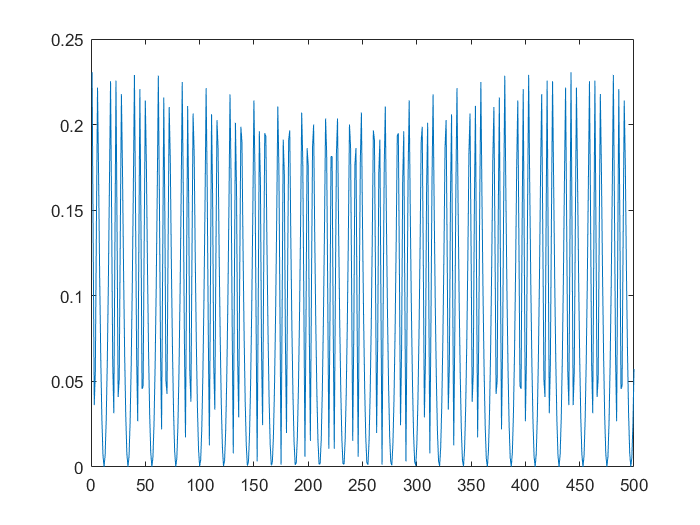

x_diff = abs(x - x_quant');
plot(1:samples, x_diff(1:samples))


"Suma szumu kwantyzacji"

ans = "Suma szumu kwantyzacji"

sum(x_diff)

ans = 2.1299e+04


x_diff_2 = abs(x - x_quant_dither');
plot(1:samples, x_diff(1:samples))


"Suma szumu kwantyzacji po ditheringu"

ans = "Suma szumu kwantyzacji po ditheringu"

sum(x_diff_2)

ans = 5.0486e+04

Wyznaczenie FFT

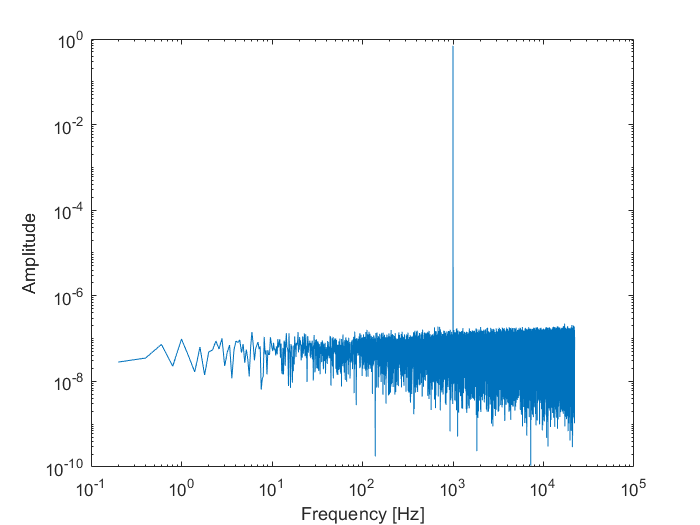

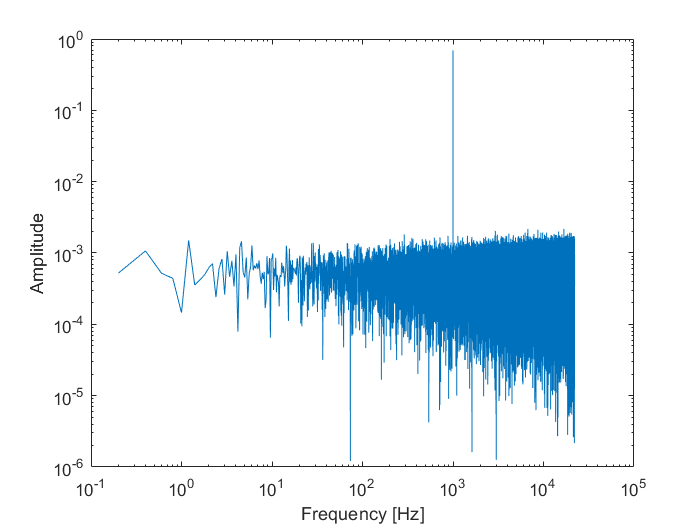



figure(1)
[y, P] = fft_plot(x, length, Fs);
figure(2)
[y_2, P_2] = fft_plot(x_dither, length, Fs);

figure(3)
[y_quant, P_quant] = fft_plot(x, length, Fs);
figure(4)
[y_quant_2, P_quant_2] = fft_plot(x_dither, length, Fs);

sound(x_quant, Fs, 8)
pause(7);

sound(x_quant_dither, Fs, 8)


sum(P)

ans = 0.6982

sum(P_quant)

ans = 0.6982

sum(P_quant_2)

ans = 60.7577